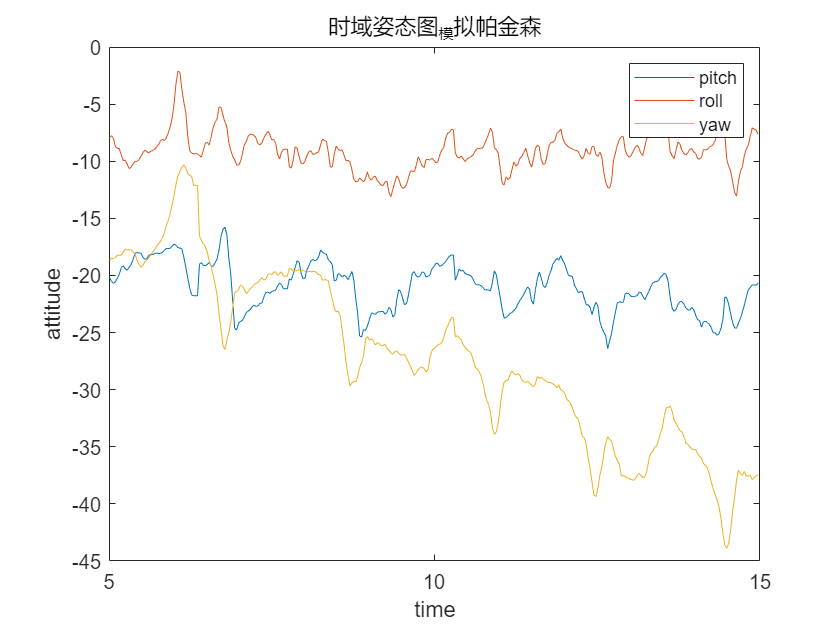

plot(dataset_pd{:, "time"}, dataset_pd{:, "pitch"}, dataset_pd{:, "time"}, dataset_pd{:, "roll"}, dataset_pd{:, "time"}, dataset_pd{:, "yaw"});
xlabel("time")
ylabel("attitude")
title('时域姿态图_模拟帕金森')
legend('pitch', 'roll', 'yaw')

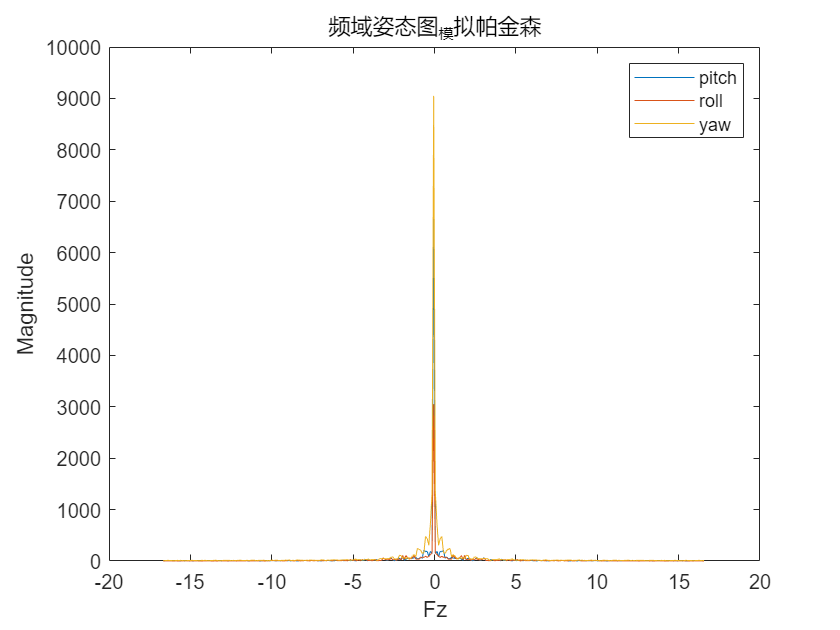

dataset_pitch_f = fft(dataset_pd{:, "pitch"});
pitch_fft_shift = fftshift(dataset_pitch_f);
dataset_roll_f = fft(dataset_pd{:, "roll"});
roll_fft_shift = fftshift(dataset_roll_f);
dataset_yaw_f = fft(dataset_pd{:, "yaw"});
yaw_fft_shift = fftshift(dataset_yaw_f);
Fs = 1 / 0.03;
f = Fs * (- length(dataset_pd{:, "pitch"}) / 2 : length(dataset_pd{:, "pitch"}) / 2 - 1) / length(dataset_pd{:, "pitch"});
plot(f, abs(pitch_fft_shift), f, abs(roll_fft_shift), f, abs(yaw_fft_shift));
xlabel("Fz")
ylabel("Magnitude")
title('频域姿态图_模拟帕金森')
legend('pitch', 'roll', 'yaw')

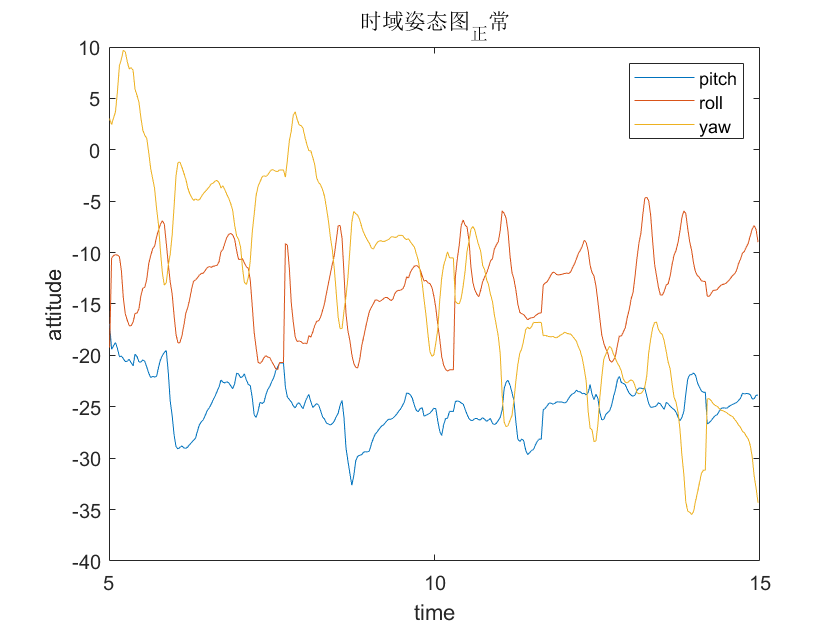

plot(dataset_upd{:, "time"}, dataset_upd{:, "pitch"}, dataset_upd{:, "time"}, dataset_upd{:, "roll"}, dataset_upd{:, "time"}, dataset_upd{:, "yaw"});
xlabel("time")
ylabel("attitude")
title('时域姿态图_正常')
legend('pitch', 'roll', 'yaw')

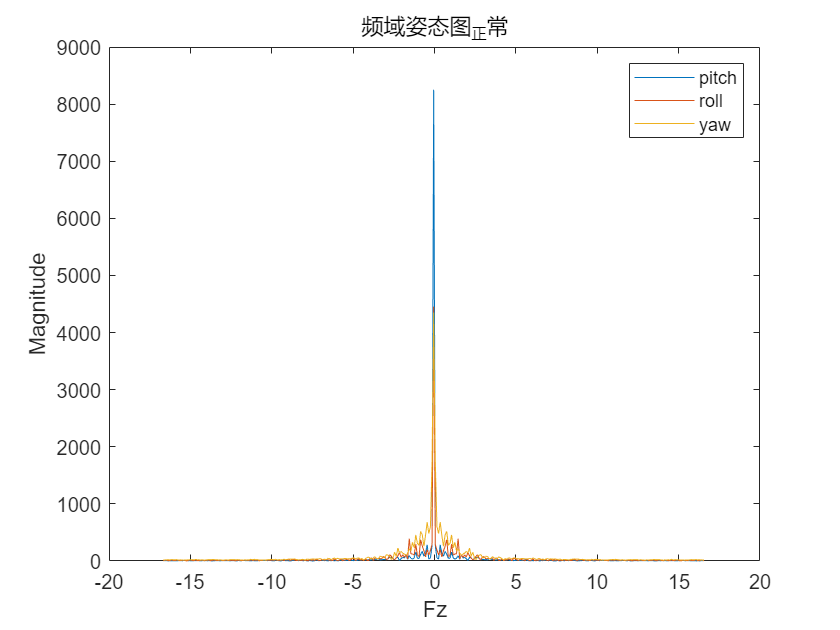

datasetu_pitch_f = fft(dataset_upd{:, "pitch"});
pitch_fft_shift_u = fftshift(datasetu_pitch_f);
datasetu_roll_f = fft(dataset_upd{:, "roll"});
roll_fft_shift_u = fftshift(datasetu_roll_f);
datasetu_yaw_f = fft(dataset_upd{:, "yaw"});
yaw_fft_shift_u = fftshift(datasetu_yaw_f);
f2 = Fs * (- length(dataset_upd{:, "pitch"}) / 2 : length(dataset_upd{:, "pitch"}) / 2 - 1) / length(dataset_upd{:, "pitch"});
plot(f2, abs(pitch_fft_shift_u), f2, abs(roll_fft_shift_u), f2, abs(yaw_fft_shift_u));
xlabel("Fz")
ylabel("Magnitude")
title('频域姿态图_正常')
legend('pitch', 'roll', 'yaw')